## Observation + motion model

% Define the colors
colors = {'green', 'red', 'white', 'blue'};

% Perception probability =  [correct incorrect]
p_O_given_C = [0.999 0.001*(1/3)];

% The probability of each adjacent cell was the previous cell of the
% current cell
p_prev_cell = 1/4;

## Making the map

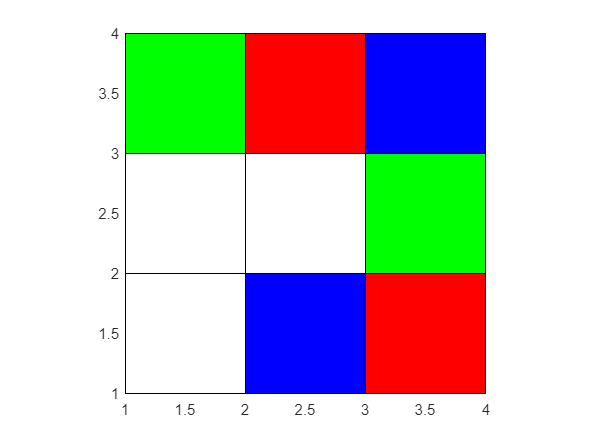

% Define the size of the map
length = 3;
width = 3;

% Initialize the map with probabilities
map = ones(width, length) * 1/(length*width);
cells = cell(width, length);

% Plot each grid with its color
for i = 1:width
    for j = 1:length
        color_index = randi([1,4]); % Generate a random index between 1 and 4
        rectangle('Position', [j, i, 1, 1], 'FaceColor', colors{color_index}, 'EdgeColor', 'k');
        cells{i,j} = colors{color_index};
    end
end

% So the stored data match the figure
%cells = flipud(cells)
cells = rot90(cells, 3);
axis([1, length+1, 1, width+1]);
axis square;

 
% We generate ten real color sequence called O_n from the map, representing
% the observations we make as the vehicle moves. This is to verify the
% algorithm, and stay unknown to us in real life.
%O_n = {cells{3,3}, cells{2,3}, cells{1,3}, cells{2,3}, cells{3,3}, cells{3,2}, cells{3,1}, cells{3,2}, cells{3,3}, cells{2,3}};

## Simulating the model

format long
% Assume the initial observation is blue
O = 'blue'; 
step = 0;
% Init normalized factor
eta = 0;

% Before any movement, calculate the map probability.
for i = 1:width
    for j = 1:length
        if strcmp(cells{j,i}, O)
            map(i,j) = p_O_given_C(1).*map(i,j);
        else
            map(i,j) = p_O_given_C(2).*map(i,j);
        end
        eta = eta + map(i,j);
    end
end


disp(['Current cell color: ', O]);

Current cell color: blue


disp(['Current step: ', num2str(step)]);

Current step: 0


% Normalize 
map = map./eta

map =    0.000166638893518   0.000166638893518   0.499416763872688
   0.000166638893518   0.000166638893518   0.000166638893518
   0.000166638893518   0.499416763872688   0.000166638893518


% Once the moving starts, iterate until a cell has probability >= 0.9999

current_position = [3,3];
% Define the possible movements: up, down, left, right
movements = [0 1; 0 -1; -1 0; 1 0];
max_prob = 0;
n = 1;
while max_prob < 0.9999
    current_color = cells{current_position(1), current_position(2)};
    disp(['Current cell color: ', current_color]);
    disp(['Current step: ', num2str(n)]);

    eta = 0;
    for i = 1:width
        for j = 1:length
            sum_previous_steps = 0;
            % Compare the color of the cell and observation to choose
            % proper probability for color perception
            if strcmp(cells{j,i}, current_color)
                map(i,j) = p_O_given_C(1);
            else
                map(i,j) = p_O_given_C(2);
            end
            
            % Calculate p_C for cells inside the map
            if 1 < j && j < length && 1 < i && i < width
                sum_previous_steps = map(j-1,i)+map(j+1,i) + map(j,i-1) + map(j,i+1) ;
            end

            % Calculate p_C for cells at the edges
            if 1 < j && j < length 
                if i == 1                 
                    sum_previous_steps = map(j-1,i)+map(j+1,i) + map(j,i+1);
                elseif i == width 
                    sum_previous_steps = map(j-1,i)+map(j+1,i) + map(j,i-1);
                end
            end
            if 1 < i && i < width
                if j == 1                 
                    sum_previous_steps = map(j,i-1) + map(j,i+1) + map(j+1,i);
                elseif j == length 
                    sum_previous_steps = map(j,i-1) + map(j,i+1) + map(j-1,i);
                end
            end   

            % Calculate p_C for cells in the corners
            if i == 1 
                if j == 1
                    sum_previous_steps = map(j+1,i) + map(j,i+1);
                elseif j == length
                    sum_previous_steps = map(j-1,i) + map(j,i+1);
                end
            end

            if i == width 
                if j == 1
                    sum_previous_steps = map(j+1,i) + map(j,i-1);
                elseif j == length
                    sum_previous_steps = map(j-1,i) + map(j,i-1);
                end
            end
            % Update the probability of the cell
            map(i,j) = map(i,j).*p_prev_cell*sum_previous_steps;
            eta = eta + map(i,j); 
        end
    end
    
    map = map./eta
    max_prob = max(map(:));

    % Choose a random direction for movement
    % Update the current position
    % Check if the new position is within the grid
    in_map = false;
    while in_map ~= true
        direction = movements(randi([1,4]), :);
        new_position = current_position + direction;
        if new_position(1) >= 1 && new_position(1) <= width && new_position(2) >= 1 && new_position(2) <= length
                current_position = new_position;
        end
    end
    n = n+1;
end

Current cell color: red


Current step: 1


map =    0.000166674515417   0.499565149664304   0.249845098609748
   0.000104171572135   0.249886737719851   0.000187498410227
   0.000041646054006   0.000124981577403   0.000078041876910
